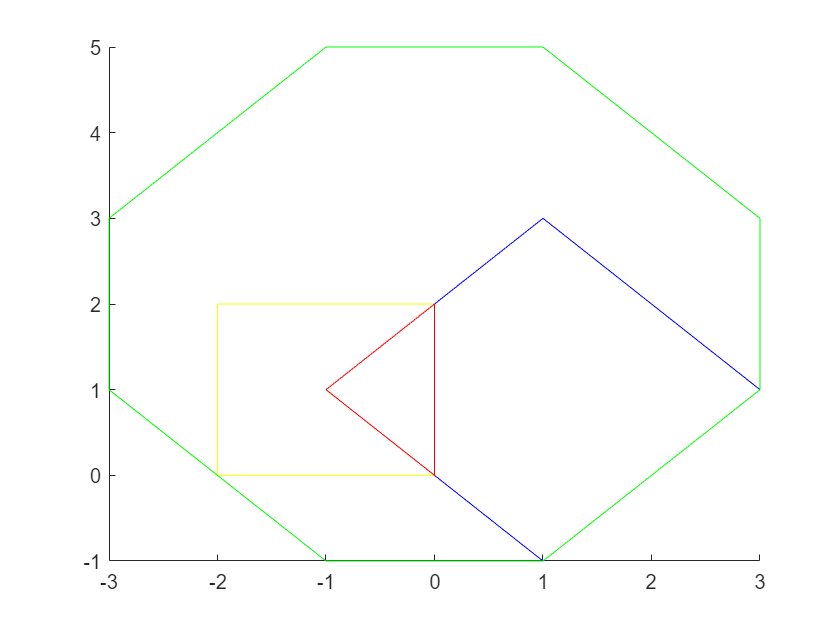

% construct zonotope
Z1 = zonotope([1 1 1; 1 -1 1]);
Z2 = zonotope([-1 1 0; 1 0 1]);

% convert zonotope Z2 to halfspace representation
P1 = mptPolytope(Z1);
P2 = mptPolytope(Z2);
P3 = P1 + P2;
P4 = P1 & P2;

% visualization
figure; hold on;
plot(P1,[1,2],'-b');
plot(P2,[1,2],'y');
plot(P3,[1,2],'g');
plot(P4,[1,2],'r');


A = P1.P.A;
b = P1.P.b;
v = P1.P.V;
n = size(A,2);
syms B d lambda_u lambda_v
%Lagrangian method
f = log(det(inv(B)));


%initialize
x0 = rand(n,n+2);
fun(x0,A,b,v);

Unrecognized function or variable 'fun'.

[x,fval,exitflag,output,lambda,grad,hessian] = fmincon(@fun,x0);

Z1 = zonotope([4 1 1; -2.4 -1 1.5]);
P1 = mptPolytope(Z1);
% Z2 = zonotope([-1 1 0; 1 0 1]);
% P2 = mptPolytope(Z2);
% P3 = P1 & P2;

A = P1.P.A;
b = P1.P.b;
m = size(A,1);
n = size(A,2);
cvx_begin
    variable B(n,n) symmetric
    variable d(n)
    maximize( det_rootn( B ) )
    subject to
       for i = 1:m
           norm( B*A(i,:)', 2 ) + A(i,:)*d <= b(i);
       end
cvx_end
[U,S,V] = svd(B);
Q = U * (S.*S)* U';
c = [1 0;0 1];
[U_,S_,V_] = svd(c);
Q_ = U_ * (S_.*S_)* U_';
E_ = ellipsoid(Q_,d);
plot(E_);
ZE = zonotope(E_,8,'inner:norm');
plot(ZE);
tic
EE = B * ZE; 
new_g = EE.Z(:,2:end);
EE_new = zonotope(d,new_g);
toc
plot(EE);
hold on;
% B_ = normalize(B,'norm');
clf;
%representing ellipsoid with CORA
E = ellipsoid(Q,d);
% E_ = ellipsoid(B_,d);
tic
ZE = zonotope(E,8,'inner:norm');
toc
% ZE_ = zonotope(E_,8,'inner:norm');
% plot(E);
hold on;
% plot(ZE);
% plot(zonotope(E,8,'inner:norm')); 
% make the plots
noangles = 200;
angles   = linspace( 0, 2 * pi, noangles );
ellipse_inner  = B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );

%try to creat zonotope from ellipsoid
nog = 8; %number of generators
angles = linspace( -pi/2, pi/2, nog);
ori_gen =  [cos(angles) ; sin(angles)]; % base generator from circle
tran_gen = normalize(B,'norm') * ori_gen/4; % transformed generator for ellipsoid
ZZ_E = zonotope(d,tran_gen);



hold on;
% plot( ellipse_inner(1,:), ellipse_inner(2,:), 'r--' );
hold on;
plot(P1);
% plot(ZE);
% plot(ZZ_E);
% plot(tran_gen(1,:),tran_gen(2,:),'b--');

clf
e = ellipsoid([1 0;0 1],[0;0]);
plot(e);
hold on;
plot(zonotope(e,8,'inner:norm')); 

norm_B = normalize(B,'norm');
ratio = B/norm_B
syms x;
fmin = @(x) norm((B * [cos(x);sin(x)]),2);
fmax = @(x) -norm((B * [cos(x);sin(x)]),2);
lb = 0;
ub = 2 * pi;
A = [];
b = [];
Aeq = [];
beq = [];
x0 = pi;
[alpha_min,short_axis] = fmincon(fmin,x0,A,b,Aeq,beq,lb,ub);
[alpha_max,long_axis] = fmincon(fmax,x0,A,b,Aeq,beq,lb,ub);
Q = [cos(alpha_min) cos(alpha_max);sin(alpha_min) sin(alpha_max)]*diag([short_axis^2 long_axis^2])*[cos(alpha_min) cos(alpha_max);sin(alpha_min) sin(alpha_max)]'
Q_ = U * (S.*S)* U';
E = ellipsoid(Q,d);
E_ = ellipsoid(Q_,d);
noangles = 200;
angles   = linspace( 0, 2 * pi, noangles );
ellipse_inner  = B * [ cos(angles) ; sin(angles) ] + d * ones( 1, noangles );
figure();
hold on;
xlim([-5 5.5]);ylim([-5 5.5]);
% plot(E);
plot(E_);
% figure();
% xlim([2.5 5.5]);ylim([-5 -1]);
% plot(E_);
% figure();
% xlim([2.5 5.5]);ylim([-5 -1]);
plot(ellipse_inner(1,:), ellipse_inner(2,:),'b--');

%try to create higher dimensional generator for zonotope

clear
Z1 = zonotope([1.2 1 1; 1.5 -1 1]);
Z2 = zonotope([0.5 1 1; 1.9 -1 1]);
Z3 = Z1 & Z2;
plot(Z1,[1,2],'Color',[0.9290 0.6940 0.1250],'LineWidth',1);
hold on;
plot(Z2,[1,2],'b','LineWidth',1);
hold on;
plot(Z3,[1,2],'r','LineWidth',1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% convert zonotope Z2 to halfspace representation
P1 = mptPolytope(Z1);
P2 = mptPolytope(Z2);
P3 = P1 & P2;
A = P3.P.A

A =    -0.7071   -0.7071
    0.7071   -0.7071
    0.7071    0.7071
   -0.7071    0.7071
   -0.7071   -0.7071
    0.7071   -0.7071
    0.7071    0.7071
   -0.7071    0.7071


b = P3.P.b

b =    -0.4950
    1.2021
    3.3234
    1.6263
   -0.2828
    0.4243
    3.1113
    2.4042


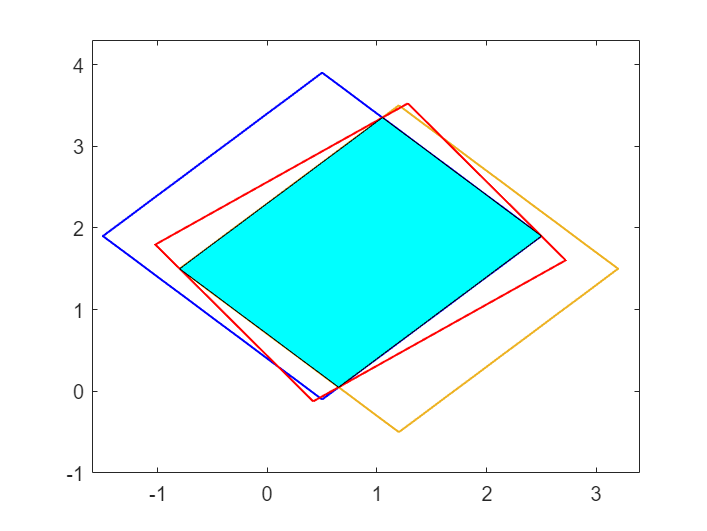


xlim([-1.6,3.4]);
ylim([-1,4.3])

% [x1,y1] = lineintersection(-A(1,:),-b(1),-A(4,:),-b(4))
% plot(x1,y1,'*')
x1 = -0.8;
x2 = 1.05;
x3 = 2.5;
x4 = 0.65;
y1 = 1.5;
y2 = 3.35;
y3 = 1.9;
y4 = 0.05;
fill([x1,x2,x3,x4],[y1,y2,y3,y4],'c')

hold off




figure()
fimplicit(@(x,y) A(1,1)*x+A(1,2)*y-b(1)) 
hold on;
fimplicit(@(x,y) A(7,1)*x+A(7,2)*y-b(7)) 
hold on;
fimplicit(@(x,y) A(6,1)*x+A(6,2)*y-b(6)) 
hold on;
fimplicit(@(x,y) A(4,1)*x+A(4,2)*y-b(4))
xlim([-1,3]);
ylim([-0.2,4])
% fill([x1,x2,x3,x4],[y1,y2,y3,y4],'c')
% hold on;
plot(P3,[1 2],'Color',[0.9290 0.6940 0.1250],'LineWidth',2)
hold on;
% AA = A([1,4,6,7],:);
% bb = -b([1,4,6,7]);
m = size(A,1);
n = size(A,2);
cvx_begin
        variable B(n,n) symmetric
        variable d(n)
        maximize( det_rootn( B ) )
        subject to
           for i = 1:m
               norm( B*A(i,:)', 2 ) + A(i,:)*d <= b(i);
           end
cvx_end

 
Calling SDPT3 4.0: 46 variables, 18 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 18
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of socp   var  = 24,   num. of socp blk  =  8
 dim. of linear var  =  9
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.9e+01|6.3e+00|1.7e+03| 3.919184e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.717|7.4e-06|1.8e+00|5.4e+02| 9.4

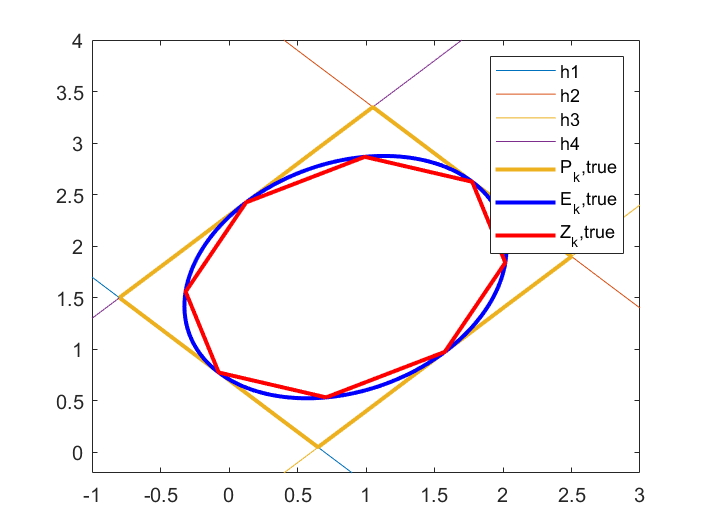




c = eye(2);
%     % svd method
    [U,S,V] = svd(B);
    Q = U * (S.*S)* U';
    E = ellipsoid(Q,d);
    ZE_new = zonotope(E,8,'inner:norm');

% EE = B * ZE; 
% new_g = EE.Z(:,2:end);
% ZE_new = zonotope(d,new_g);
plot(E,[1 2],'b','LineWidth',2)
hold on;
plot(ZE_new,[1 2],'r','LineWidth',2);
legend('h1','h2','h3','h4','P_k,true','E_k,true','Z_k,true')
hold off;

function [x,y] = lineintersection(A1,B1,A2,B2)
    a1 = A1(1)
    b1 = A1(2)
    c1 = B1;
    a2 = A2(1);
    b2 = A2(2);
    c2 = B2;
    x = (b2*c1 - b1*c2) / (a1*b2 - a2*b1);
    y = (a1*c2 - a2*c1) / (a1*b2 - a2*b1);
end